# Training neural networks

## Create a toy dataset

Create a toy data set with samples from the same class falling in diagonally opposite quadrants 

n_samples = 100; 
[X,Y,g] = generateToyData(n_samples);


%plotting 
gscatter(X,Y,g);

## Create a neural network

create_simple_dnn
% S = load("trainingLessonData.mat"); 
% net = S.net;

## Classification before training

Examine how the untrained neural network classifies the points in the plane 

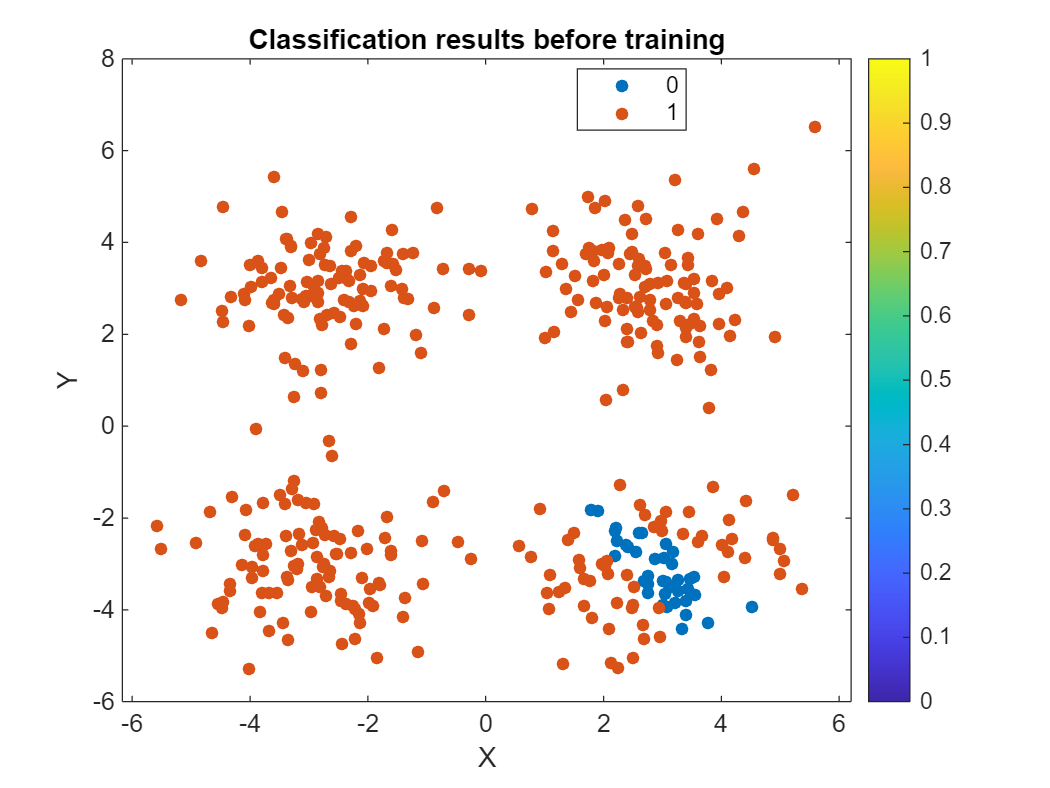

% Evaluate the network on the grid points
gridPoints = [X, Y];
% Since the output layer is a softmax layer, the predictions will be probabilities
% Get the class with the highest probability
c = predict(net, gridPoints);
g1 = zeros(size(c,1),1); 
g1(c(:,1)<=c(:,2)) = 1; 

% Create the scatter plot
figure;
gscatter(X,Y,g1)
colorbar

title('Classification results before training');

## Training the neural network

What does training the neural network mean? 

- Say you have some data points $x_1, x_2,\ldots, x_N$, and each data has a label $l_1,l_2,\ldots,l_N$. 

- The neural network we constructed is a function which takes a data point as an input and outputs a probability distribution 

$f(x_i) = P_i =  \left( p_1,p_2,\ldots,p_m \right)$ , where $m$ is the number of labels. 

- If $x_i$ is associated with the first label, then ideally, we want $f(x_i)$ to output $\left(1,0,\ldots,0\right)$ as the probability distribution. Let's call this $P_{ti}$ as the true probability distribution. 

- Then, the training process will adjust $f$ by trying to minimize $\sum_i{loss(P_i, P_{ti})}$

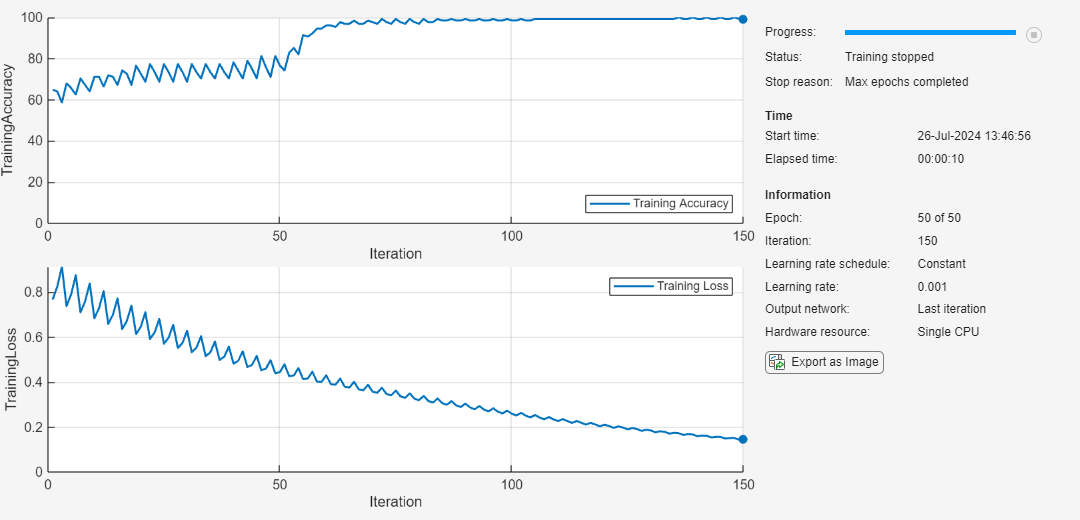

options = trainingOptions("adam", ...
    MaxEpochs=50, ...
    Verbose=false, ...
    Plots="training-progress", ...
    Metrics="accuracy");

netTrained = trainnet(gridPoints, categorical(g), net, 'crossentropy',options);

S = load("trainingLessonData.mat"); 
netTrained = S.netTrained; 

## Classification after training

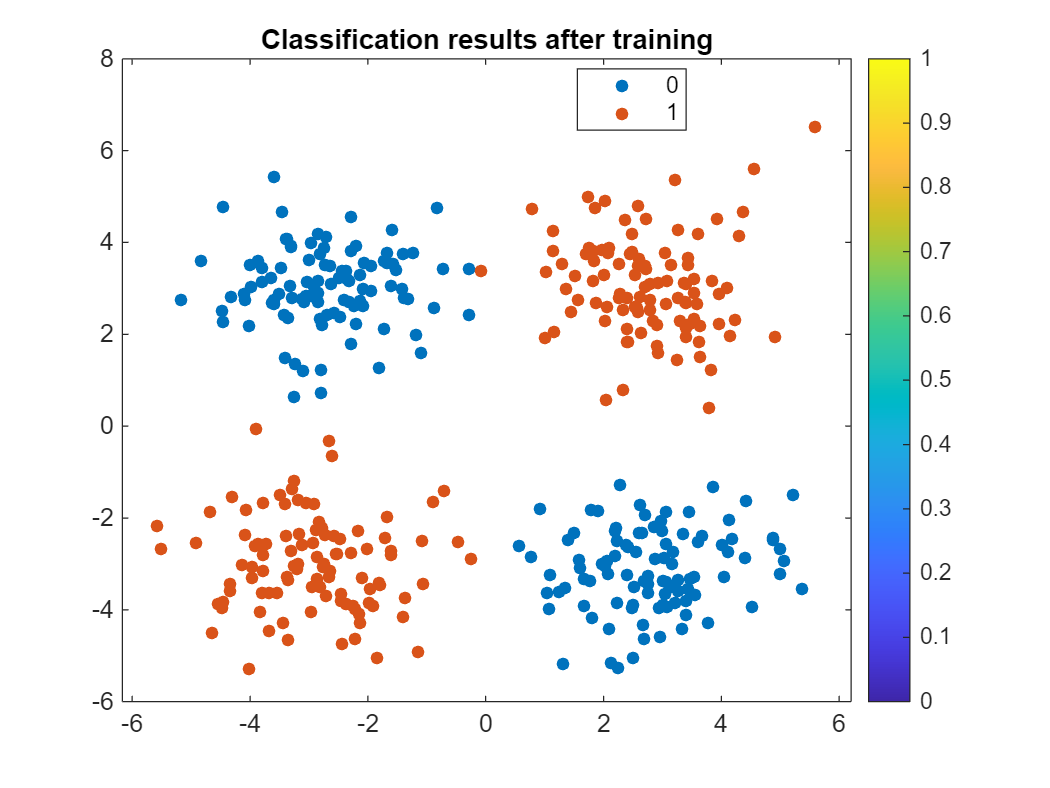


c = predict(netTrained, gridPoints);
g2 = zeros(size(c,1),1); 
g2(c(:,1)>=c(:,2)) = 0; 
g2(c(:,1)<c(:,2)) = 1; 
g2 = categorical(g2); 

% Create the scatter plot
figure;
gscatter(gridPoints(:,1), gridPoints(:,2),g2)
colorbar
title('Classification results after training');

Helper function to generate the toy dataset

function [X,Y,g] = generateToyData(n_samples)
% Number of samples per class


% Generate samples for class 1 (first and third quadrants)
class1_x1 = randn(n_samples, 1) + 3; % first quadrant
class1_y1 = randn(n_samples, 1) + 3;

class1_x2 = randn(n_samples, 1) - 3; % third quadrant
class1_y2 = randn(n_samples, 1) - 3;

% Combine class 1 samples
class1_x = [class1_x1; class1_x2];
class1_y = [class1_y1; class1_y2];
class1 = [class1_x, class1_y];

% Generate samples for class 2 (second and fourth quadrants)
class2_x1 = randn(n_samples, 1) - 3; % second quadrant
class2_y1 = randn(n_samples, 1) + 3;

class2_x2 = randn(n_samples, 1) + 3; % fourth quadrant
class2_y2 = randn(n_samples, 1) - 3;

% Combine class 2 samples
class2_x = [class2_x1; class2_x2];
class2_y = [class2_y1; class2_y2];
class2 = [class2_x, class2_y];

X = [class1(:,1); class2(:,1)]; 
Y = [class1(:,2); class2(:,2)]; 
g = zeros(size(X)); 
g(1:2*n_samples) = 1; 


end